load('results\2mM-FeSO4-NiSO4-20181207\I0_Idark.mat');

I0_Array = I0_dark_2_I0_reaction2(:, 2);
dark_Array = dark_reaction2(:, 2);

fileName = "Lin\Research_Project\solei beamtime\2018-12\2mM-FeSO4-NiSO4-20181207\350-450mv\I-reaction11_f000000000000_15_ascii\I-reaction11_f000000000000_15_1.txt";
I_Array = getStatics(fileName);

xas_Array = {result_350_450, result_450_450, result_450_500, result_450_550, result_500_500, ...
    Fe2O3_result, Fefoil_result, FeO_result};

% select important part ---- (400-700)
% xas_Array = {xas_Array(400:700, :)};

% 
% xas_Array = rmAbnormalValue(xas_Array);
% XAS_Array_Gauss = rmPointsByGaussian(xas_Array);

% subplot(3,1,1);
% plotXAS(xas_Array);
% subplot(3,1,2);
% plotXAS(XAS_Array_Gauss);
% subplot(3,1,3);
% plotXAS(movmean(XAS_Array_Gauss, 5));

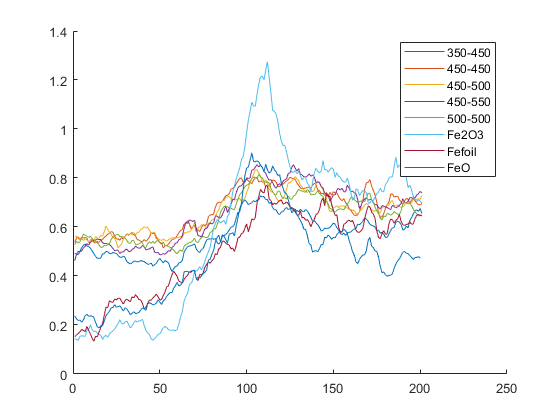

d = {zeros(5)};
XAS_Array_Gauss = {zeros(5)};
figure;
hold on;
for i=1:1:length(xas_Array)
    a = xas_Array{i}(400:600, :);
    d{i} = rmAbnormalValue(a);
    XAS_Array_Gauss{i} = rmPointsByGaussian(d{i});
    plotXAS(movmean(XAS_Array_Gauss{i}, 7));
    hold on;
end
legend({'350-450', '450-450', '450-500', '450-550', '500-500', ...
    "Fe2O3", "Fefoil", "FeO"});
hold off;

function result=rmAbnormalValue(sourceArray)
    result = sourceArray(~isnan(sourceArray));
    result = result(~isinf(result));
end

function []= plotXAS(sourceArray)
    x_Axis = 1:1:length(sourceArray);
    plot(x_Axis, sourceArray);
end

function result=rmPointsByGaussian(sourceArray)
    if(isnan(sourceArray))
        disp('the array includes Nan value!');
        return;
    end
    ave = mean(sourceArray);
    stand = std(sourceArray);
    
    for(i=1:1:length(sourceArray))
        if(abs(sourceArray(i) - ave) > 3 * stand)
            sourceArray(i) = -123412;
        end
    end
    result = sourceArray(sourceArray ~= (-123412));
end